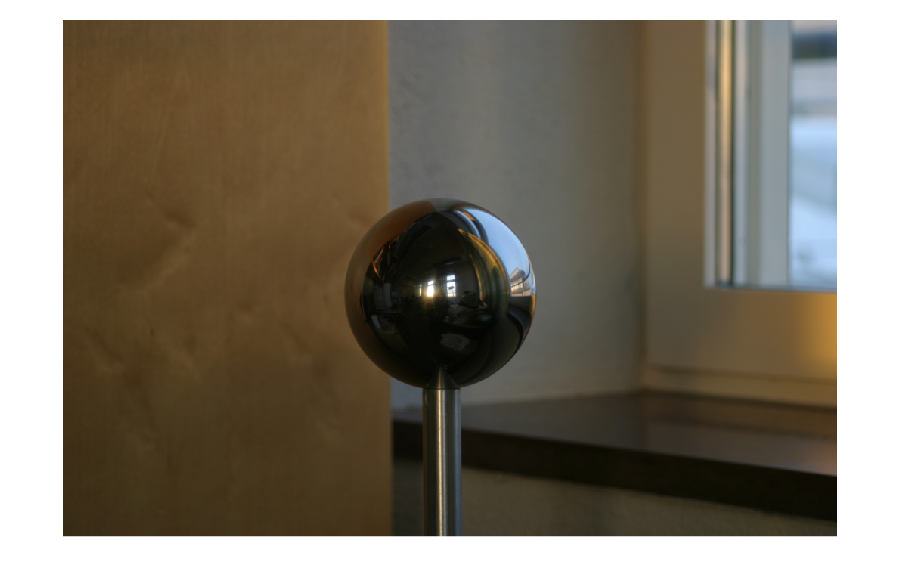

image = im2double(imread("../HDR\ImagesSmall\Img10.tiff"));
figure;
imshow(image);

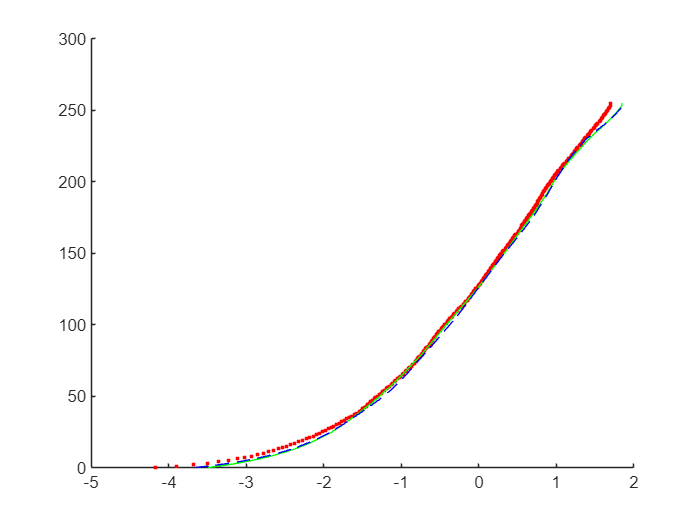


% Dela upp RGB-kanalerna i imOG:
[R,G,B] = imsplit(image);

% Gör R-kanalen till en 1D-vektor, kalla den imJ:
imJ = R(:);

% Pixel location i:
locI = imJ(1);

gCurve = makegfun;
y = linspace(0, 255, 256)';

%[gCurve,lE] = gsolve(Z,B,l,w)

figure;
hold on;
plot(gCurve(:,1), y, 'r.');
plot(gCurve(:,2), y, 'g-');
plot(gCurve(:,3), y, 'b--');